# Homework 5

## [✔] ADSI Problem 4.2: Autocorrelation functions from plot

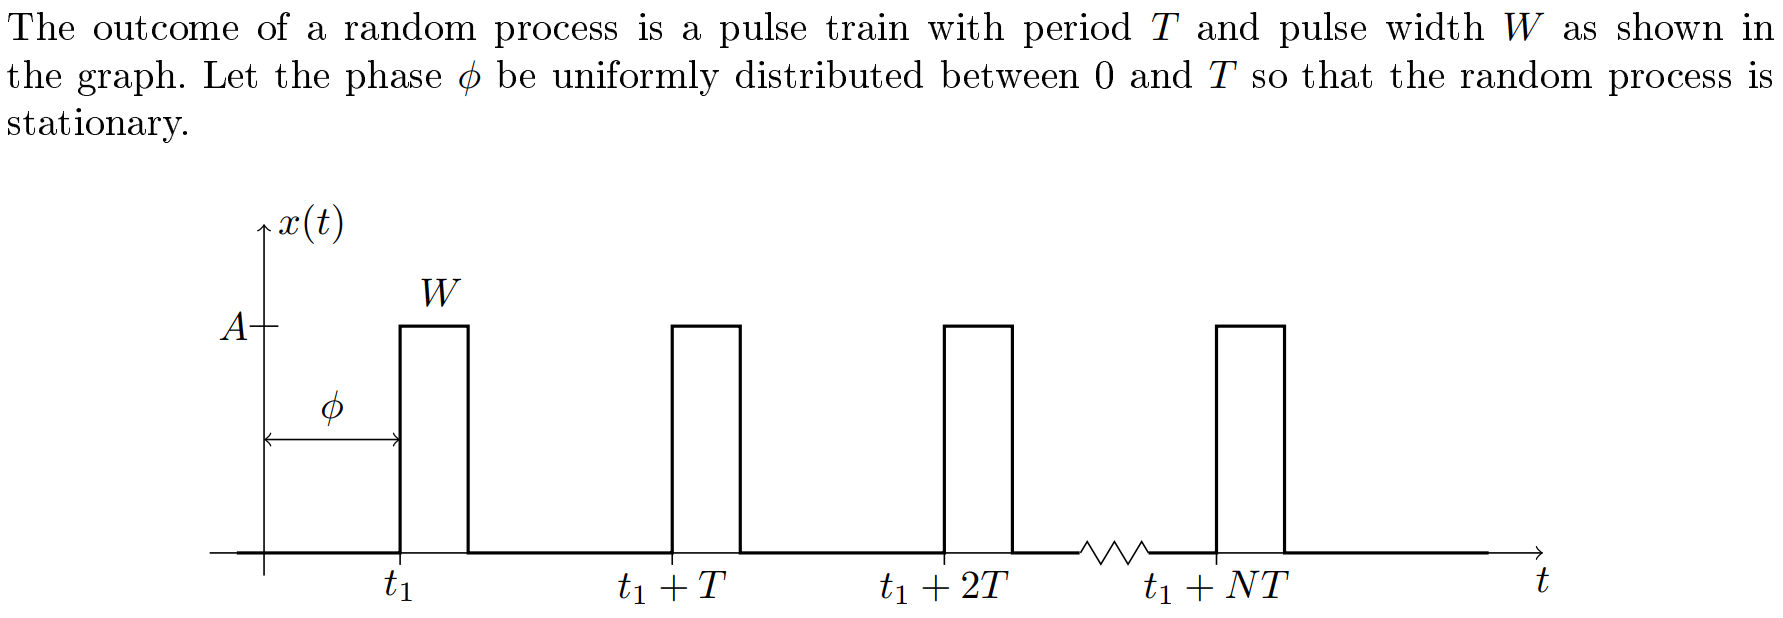

### 1) Sketch and explain what the autocorrelation looks like

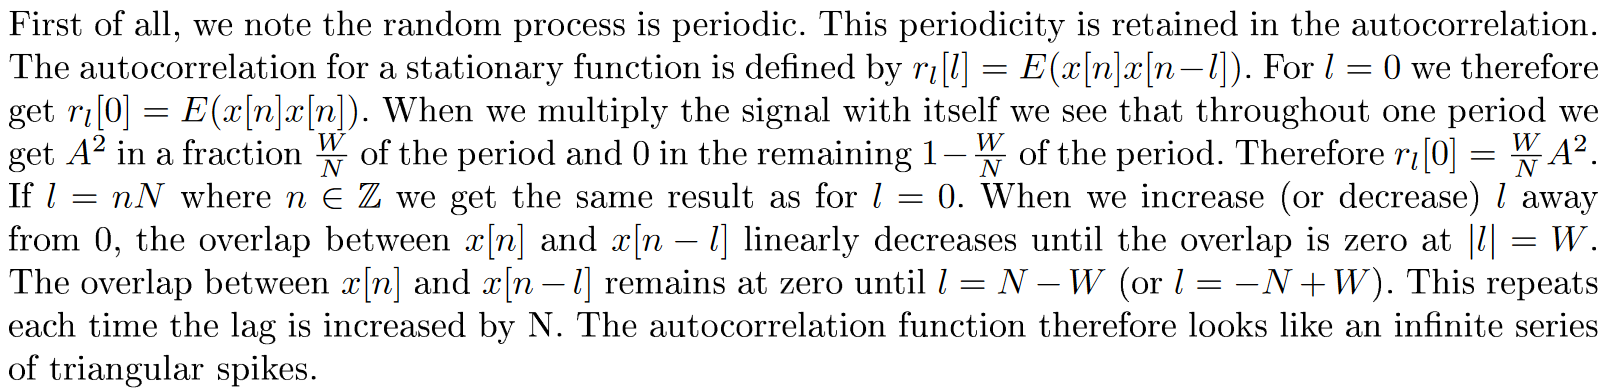

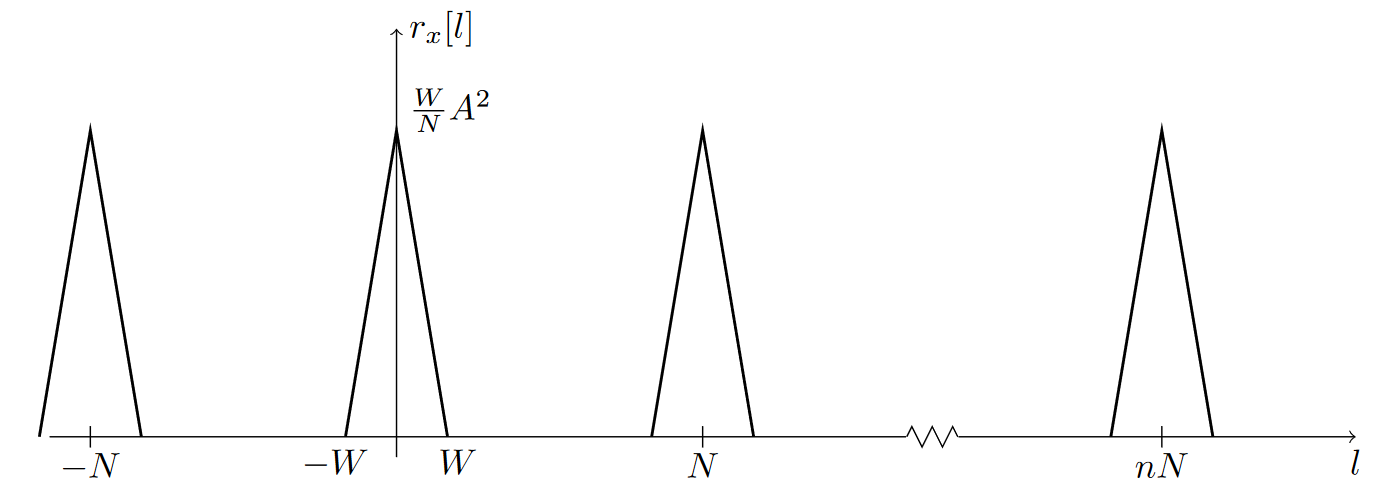

### 2) Use computer simulations to verify the above result

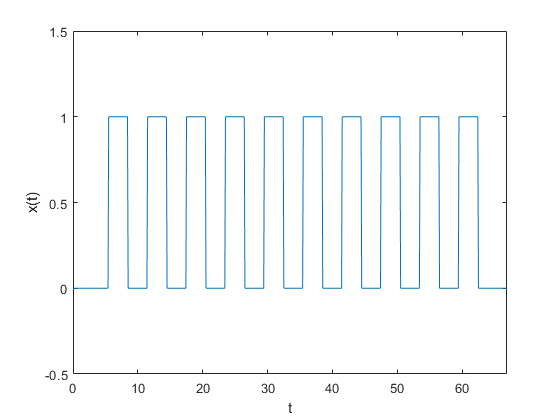

A = 1;
W = 3;  % Pulse width
T = 6; % Period width
N = 10;

% Random number from a uniform distribution in the open interval (a, b)
% a = 0; b = T; random_number = (b-a)*rand + a
phi = T*rand(1);

maxT = phi+W/2 + T*N;

t=0:.1:maxT;   % Time vector 
d= phi+W/2:T:phi+W/2+T*N-1; % Delay vector
y = pulstran(t,d,'rectpuls', W);
plot(t,y)

ylabel('x(t)');
xlabel('t');
ylim([-0.5, A+0.5]);
xlim([0, max(t)]);

Autocorrelation is symmetrical around zero.

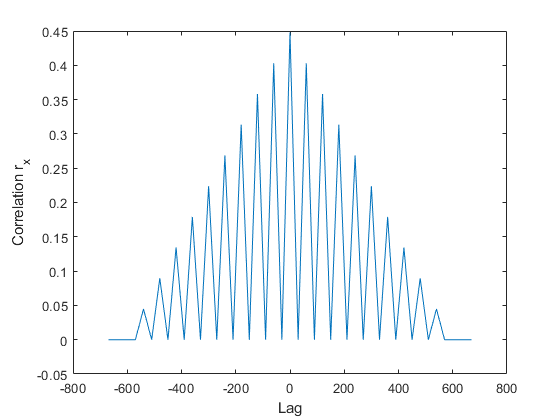

[r_xx, lags] = xcorr(y, 'biased');
plot(lags, r_xx);
ylabel('Correlation r_x');
xlabel('Lag')

## [✔] ADSI Problem 4.4: Autocorrelation of complex signals

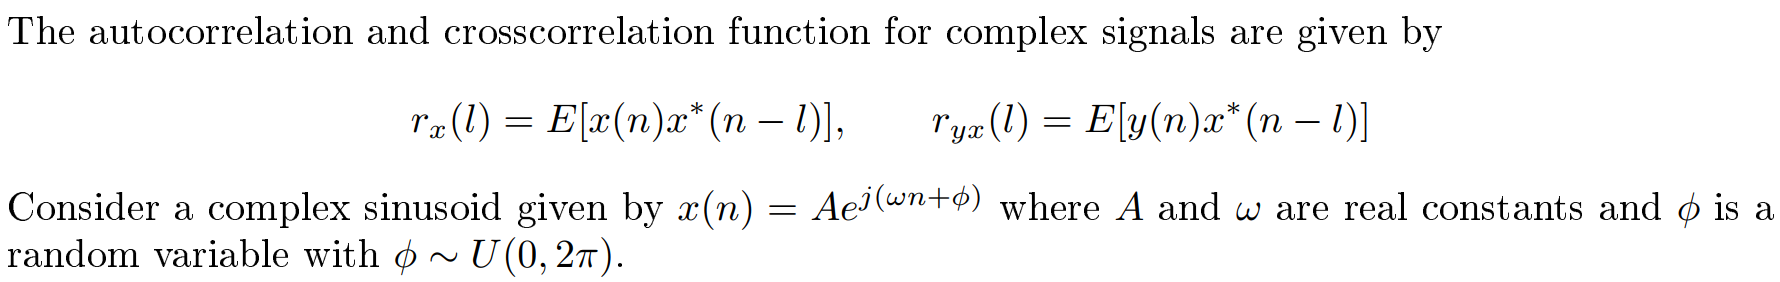

### 1) Compute the analytic expression for the autocorrelation of the complex sinusoid 

The autocorrelation function for complex signals can be computed as:


$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack x\left(n\right)x^* \left(n-\ell \right)\right\rbrack$$


Plugging the given complex sinusiod into the formula, we get:


$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack A\;e^{j\left(\omega n+\phi \right)} A\;e^{-j\left(\omega \left(n-\ell \right)+\phi \right)} \right\rbrack$$


Since $A$ is a constant, we can move it outside the expected value:


$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\left(\omega n+\phi \right)} \;e^{-j\left(\omega \left(n-\ell \right)+\phi \right)} \right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi } \;e^{-j\omega n+j\omega \ell -j\phi } \right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi +\left(-j\omega n+j\omega \ell -j\phi \right)} \;\right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi -j\omega n+j\omega \ell -j\phi } \;\right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega \ell } \;\right\rbrack$$


We know that $E\left\lbrack e^{j\omega \ell } \right\rbrack =e^{j\omega \ell }$ because the expected value of a constant is just the constant itself. Notice that $\phi$ is no longer in the expression $e^{j\omega \ell }$. Therefore, the autocorrelation of the complex sinusoid is:


$$r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


### 2) How are rx(l) and rx(-l) related for a complex signal?

In 1) we found an analytical expression for $r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell }$

Let us compute the autocorrelation for $-\ell$:


$$r_{\textrm{xx}} \left(-\ell \right)=E\left\lbrack x\left(n\right)x^* \left(n+\ell \right)\right\rbrack$$


Suppose $m=n+\ell$. Then we can write $n=m-\ell$. Let us substitute all $n$ with $m$ in the above expression:


$$r_{\textrm{xx}} \left(-\ell \right)=E\left\lbrack x\left(m-\ell \right)x^* \left(m\right)\right\rbrack$$


Computing the complex conjucate of the expectation we get:


$$r_{\textrm{xx}} \left(-\ell \right)=E{\left\lbrack x^* \left(m-\ell \right)x\left(m\right)\right\rbrack }^*$$



$$r_{\textrm{xx}} \left(-\ell \right)=E{\left\lbrack x\left(m\right)x^* \left(m-\ell \right)\right\rbrack }^*$$


Since $r_{\textrm{xx}}^* \left(\ell \right)=E{\left\lbrack x\left(m\right)x^* \left(m-\ell \right)\right\rbrack }^*$, we know that:


$$r_{\textrm{xx}} \left(-\ell \right)=r_{\textrm{xx}}^* \left(\ell \right)$$


### 3) Compute the autocorrelation of a real signal

We can use the result from 1)


$$r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


Since the result from 1) uses Euler, we need to convert the signal to complex exponential. 

We use the relation $\mathrm{cos}\left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$


$$x\left(n\right)=A\;\mathrm{cos}\left(\omega \;n+\phi \right)$$



$$x\left(n\right)=\frac{A}{2}\;\left(e^{j\left(\omega n+\phi \right)} +e^{-j\left(\omega n+\phi \right)} \right)$$



$$x\left(n\right)=\frac{A}{2}e^{j\left(\omega n+\phi \right)} +\frac{A}{2}e^{-j\left(\omega n+\phi \right)}$$


In 1) we found that the autocorrelation of a complex sinusoid $x\left(n\right)=A\;e^{j\left(\omega \;n+\phi \right)}$ is $r_{\textrm{xx}} \left(\ell \right)=A^2 e^{j\omega \ell }$

Therefore, the autocorrelation of the real signal is:


$$r_{\mathrm{xx}} \left(\ell \right)={\left(\frac{A}{2}\right)}^2 e^{j\omega \ell } +{\left(\frac{A}{2}\right)}^2 e^{-j\omega \ell }$$



$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}e^{j\omega \ell } +\frac{A^2 }{4}e^{-j\omega \ell }$$



$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$



$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\frac{1}{2}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$


Using the relation $\cos \left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$  we can rewrite the autocorrelation to:


$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


## [✔] ADSI Problem 4.5: Autocorrelation of distorted signals

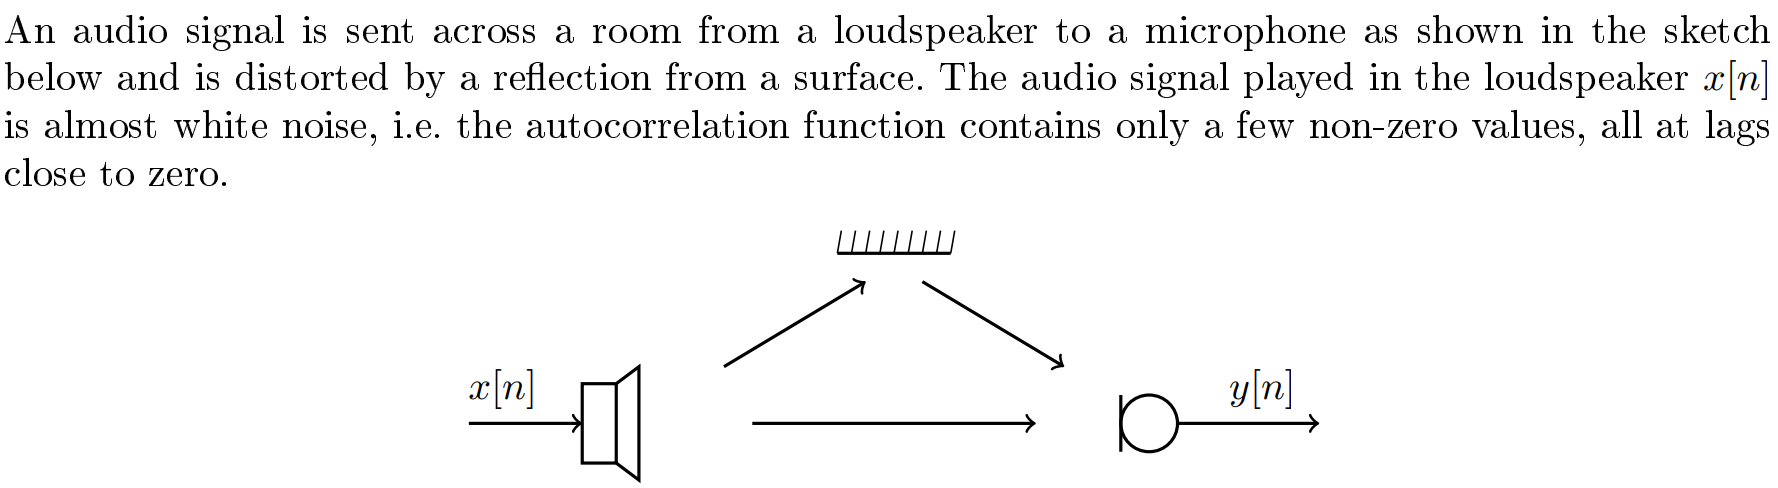

### 1) Derive autocorrelation function of the output signal

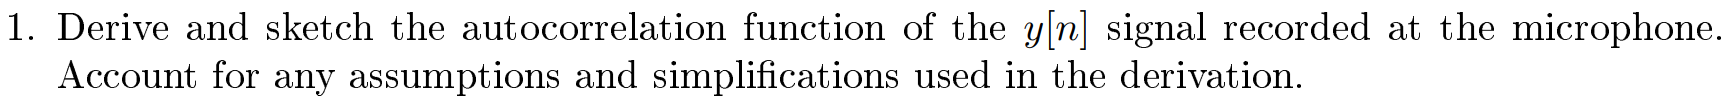

From the figure, we observed that the signal at microphone $y\left(n\right)$ is a combination of two signals.

The bottom arrow describes the signal from the loudspeaker that reaches the microphone with no distortion and no delays.

The two top arrows describes the signal that is distorted by a reflection. This means that the original signal $x\left(n\right)$ will be attenuated and delayed.

Therefore, we can describe the signal at the microphone as

    
$$y\left(n\right)=x\left(n\right)+\alpha x\left(n-D\right)$$


where

- $\alpha <1$ is the attenuation caused by the reflection

- $D$ is the delay of the original signal

The autocorrelation of $y\left(n\right)$ can be derived:


$$r_{\mathrm{yy}} \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack \left(x\left(n\right)+\alpha x\left(n-D\right)\right)\left(x\left(n-\ell \right)+\alpha x\left(n-D-\ell \right)\right)\right\rbrack$$


Multiple each terms


$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)+\alpha x\left(n\right)x\left(n-D-\ell \right)+\alpha x\left(n-D\right)x\left(n-\ell \right)+\alpha^2 x\left(n-D\right)x\left(n-D-\ell \right)\right\rbrack$$


Seperate expectation terms


$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack +E\left\lbrack \alpha x\left(n\right)x\left(n-D-\ell \right)\right\rbrack +E\left\lbrack \alpha x\left(n-D\right)x\left(n-\ell \right)\right\rbrack +E\left\lbrack \alpha^2 x\left(n-D\right)x\left(n-D-\ell \right)\right\rbrack$$


Move constants out of the expecation:


$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack +\alpha E\left\lbrack x\left(n\right)x\left(n-D-\ell \right)\right\rbrack +\alpha E\left\lbrack x\left(n-D\right)x\left(n-\ell \right)\right\rbrack +\alpha^2 E\left\lbrack x\left(n-D\right)x\left(n-D-\ell \right)\right\rbrack$$


We will use the relation $r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack$ to rewrite the expression above.

The expectation in the first term and the last term are trivial to rewrite:


$$r_{\textrm{yy}} \left(\ell \right)=r_{\mathrm{xx}} \left(\ell \right)+\alpha E\left\lbrack x\left(n\right)x\left(n-D-\ell \right)\right\rbrack +\alpha E\left\lbrack x\left(n-D\right)x\left(n-\ell \right)\right\rbrack +\alpha^2 r_{\mathrm{xx}} \left(\ell \right)$$


We know that $r_{\textrm{xx}} \left(\ell -D\right)=E\left\lbrack x\left(n\right)x\left(n-\ell -D\right)\right\rbrack$ so we want rewrite the second term:


$$r_{\textrm{yy}} \left(\ell \right)=r_{\textrm{xx}} \left(\ell \right)+\alpha r_{\textrm{xx}} \left(\ell -D\right)+\alpha E\left\lbrack x\left(n-D\right)x\left(n-\ell \right)\right\rbrack +\alpha^2 r_{\textrm{xx}} \left(\ell \right)$$


Let $m=n-D$ then $n=m+D$. Then $E\left\lbrack x\left(m\right)x\left(m-\ell +D\right)\right\rbrack$. Thus, the third term can rewritten to:


$$r_{\textrm{yy}} \left(\ell \right)=r_{\textrm{xx}} \left(\ell \right)+\alpha r_{\textrm{xx}} \left(\ell -D\right)+\alpha r_{\mathrm{xx}} \left(\ell +D\right)+\alpha^2 r_{\textrm{xx}} \left(\ell \right)$$


To make it easier to sketch the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$, we can rewrite it the expression as:


$$r_{\textrm{yy}} \left(\ell \right)=\left(1+\alpha^2 \right)r_{\textrm{xx}} \left(\ell \right)+\alpha r_{\textrm{xx}} \left(\ell -D\right)+\alpha r_{\textrm{xx}} \left(\ell +D\right)$$


From this expression, we know that there are three peaks because each autocorrelation $r_{\mathrm{xx}}$ corresponds to a peak. One peak is at lag zero, another peak at lag $-D$ and the last peak at $D$. Therefore, 

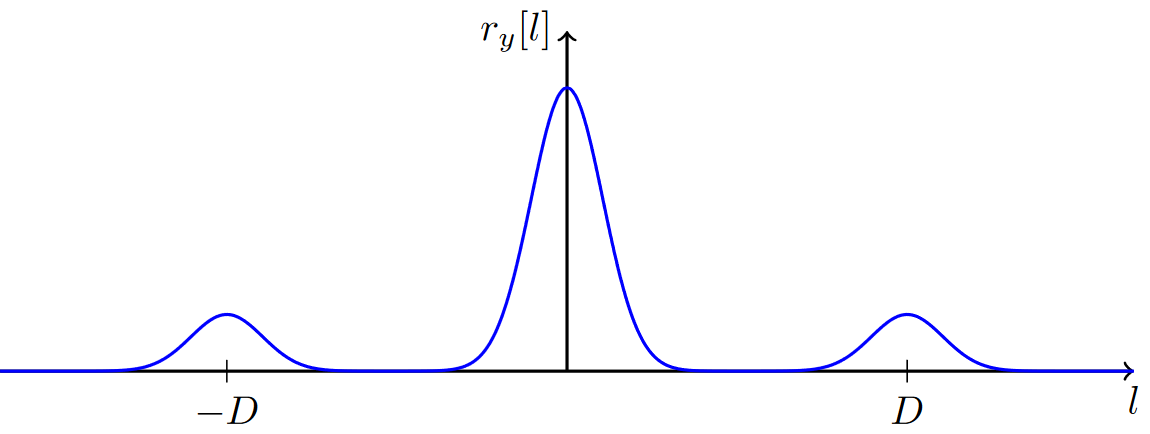

Let us check if we can see the same patterns if we simulate it in MATLAB:

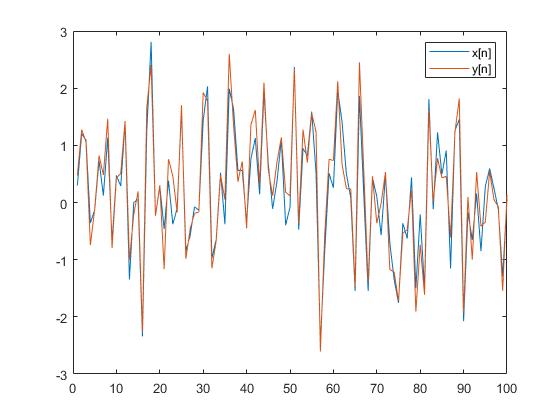

alpha = 0.3;
D = 5;
N = 100;

n = [1:N];
x = wgn(N,1,0);
y = x + alpha*circshift(x, D);
plot(n, x, n, y)
legend('x[n]', 'y[n]')

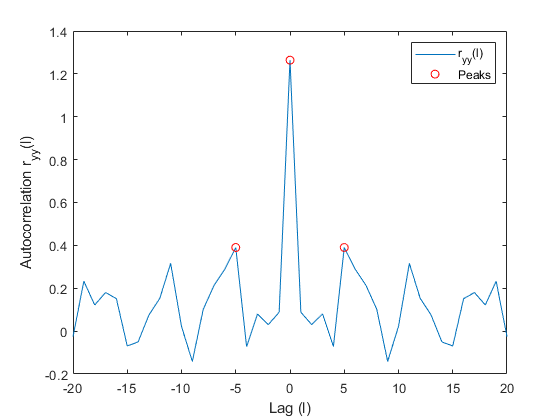

[r_yy, lags] = xcorr(y, 20, 'biased');
plot(lags, r_yy);
hold on;
plot(0, r_yy(find(lags == 0)), 'ro');
plot(D, r_yy(find(lags == D)), 'ro');
plot(-D, r_yy(find(lags == -D)), 'ro');
legend('r_{yy}(l)', 'Peaks')
ylabel('Autocorrelation r_{yy}(l)');
xlabel('Lag (l)')
hold off;

### 2) Is possible to remove the distortion from the output signal?

From our sketch, we can estimate the delay and attenuation by the position of the peaks and the amplitude ratio.

Then we create a FIR filter which substract a delayed and attenuated copy of $y\left\lbrack n\right\rbrack$:


$$z\left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack -\alpha y\left\lbrack n-D\right\rbrack$$



$$z\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\alpha x\left\lbrack n-D\right\rbrack -\alpha \left(x\left\lbrack n-D\right\rbrack +\alpha x\left\lbrack \left(n-D\right)-D\right\rbrack \right)$$



$$z\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\alpha x\left\lbrack n-D\right\rbrack -\alpha \left(x\left\lbrack n-D\right\rbrack +\alpha x\left\lbrack n-2D\right\rbrack \right)$$



$$z\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\alpha x\left\lbrack n-D\right\rbrack -\alpha x\left\lbrack n-D\right\rbrack -\alpha^2 x\left\lbrack n-2D\right\rbrack$$



$$z\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -\alpha^2 x\left\lbrack n-2D\right\rbrack$$


The result is a new signal $z\left\lbrack n\right\rbrack$ where the distortion is pushed to $2D$ and the attenuation factor is squared. 

Since $\alpha <1$, the squared attenuation $\alpha^2$ is much smaller than 1. This means the distortion component is much smaller than before.

Another approach is as follows:

The distoration corresponds to a FIR filter with the system function $H\left(z\right)=1+\alpha z^{-D}$. In principle, this can be removed using an IIR filter with the inverse system function.

## ADSI Problem 4.6: System identification

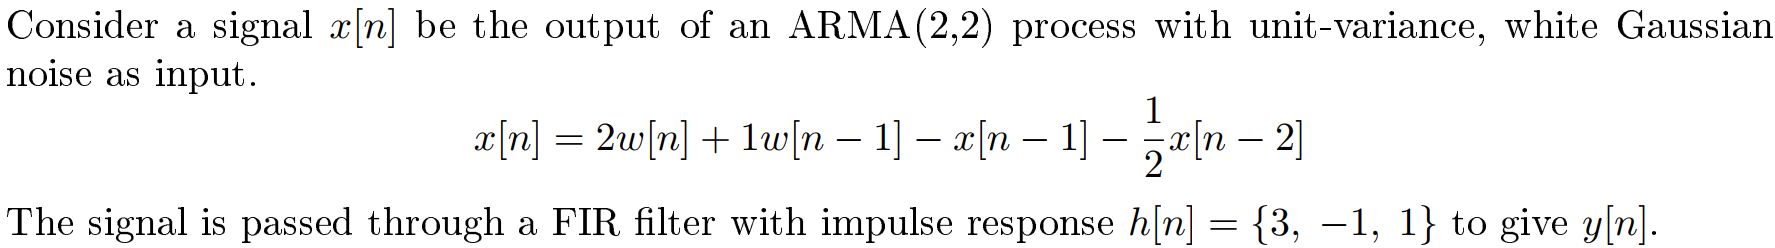

### 1) Simulate the autocorrelation and cross-correlation in MATLAB

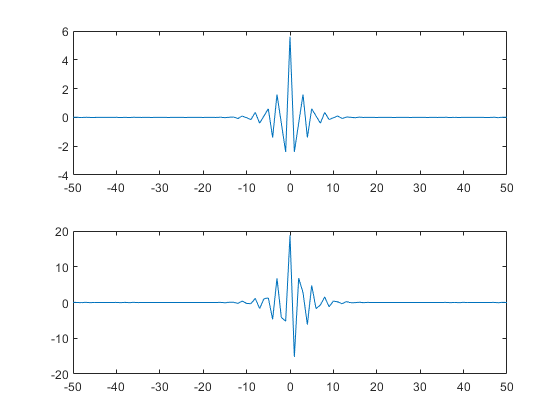

w=randn(1e6,1);
x=filter([2 1],[1 1 0.5],w);
y=filter([3 -1 1],1,x);

[rxx,lagsrxx]=xcorr(x,50,'biased');
[ryx,lagsryx]=xcorr(y,x,50,'biased');


figure(1)
subplot(211)
plot(lagsrxx,rxx)

subplot(212)
plot(lagsryx,ryx)

### 2) Compute the transfer function and impulse response from the autocorrelation

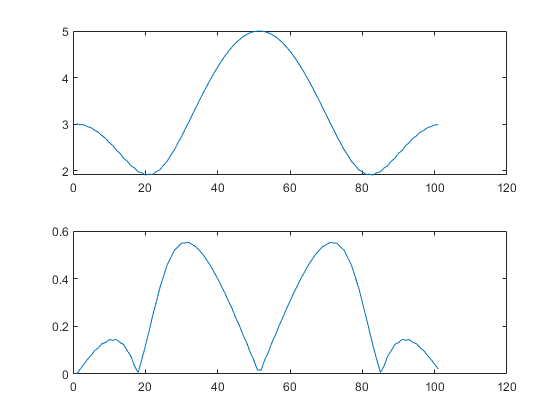

%%
Rxx=fft(rxx);
Ryx=fft(ryx);

H=Ryx./Rxx;

figure(2)
subplot(211)
plot(abs(H)) % todo: add a frequency axis and labels.
subplot(212)
plot(abs(angle(H)))

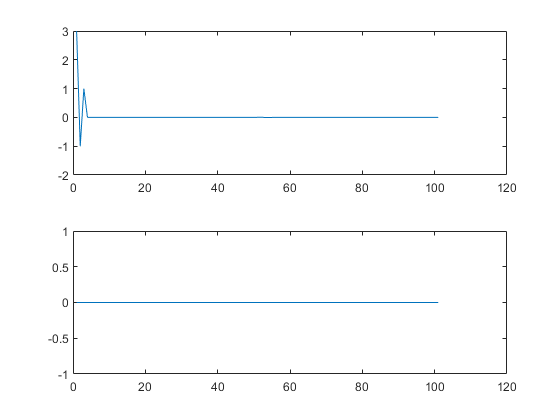


h=ifft(H);
figure(3)
subplot(211)
plot(real(h))

subplot(212)
plot(imag(h))

## Exam 2012 Problem 4: Wiener filter for recovering corrupted signal

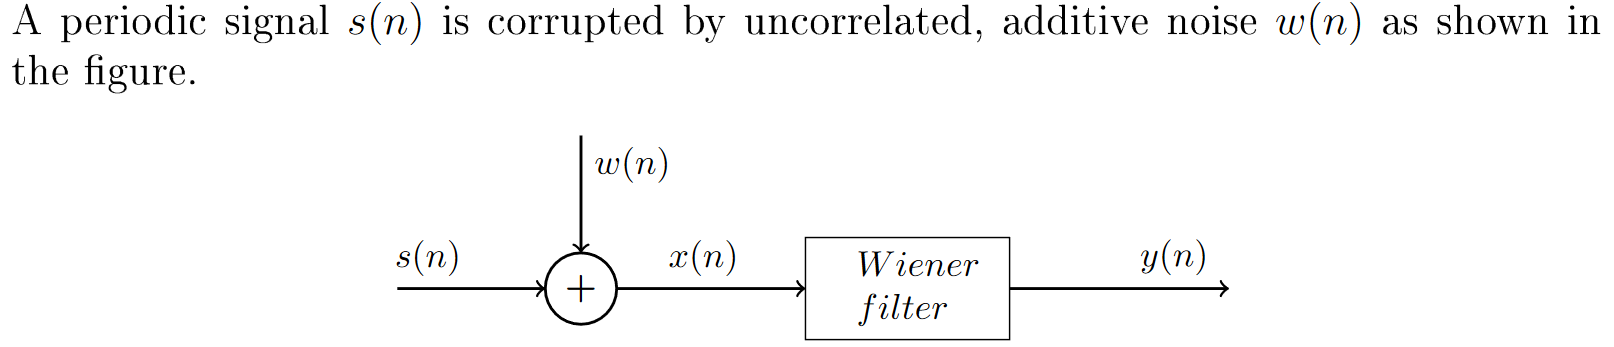

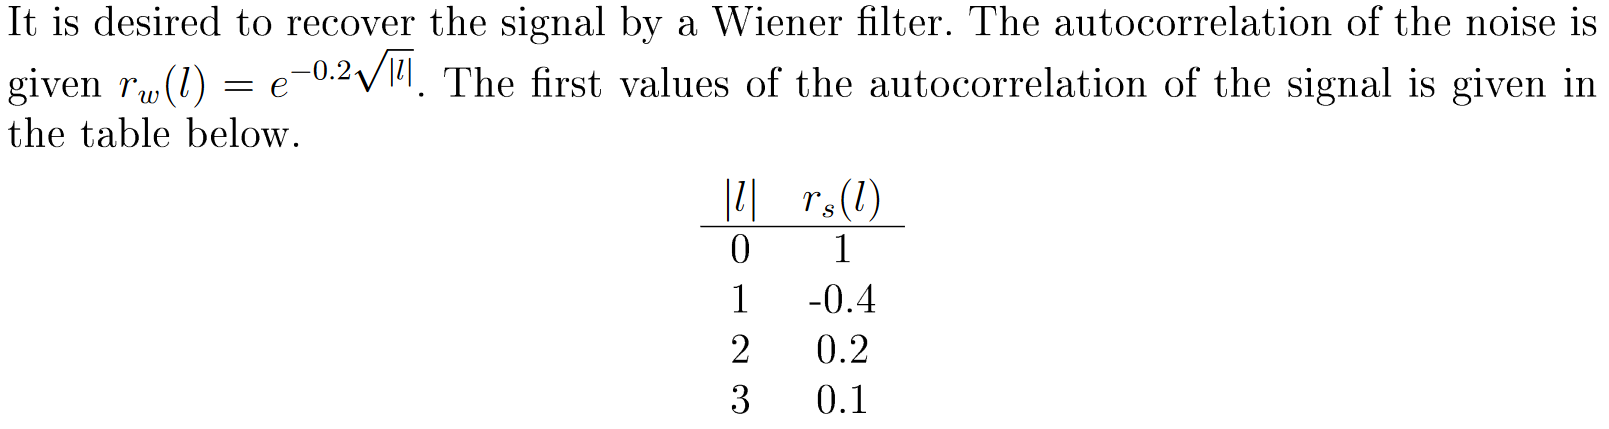

### 1) Design a 3 tap Wiener filter to recover s(n)

### 2) Calculate the minimum mean square error

### 3) Discuss another Wiener filter with 2x noise amplitude